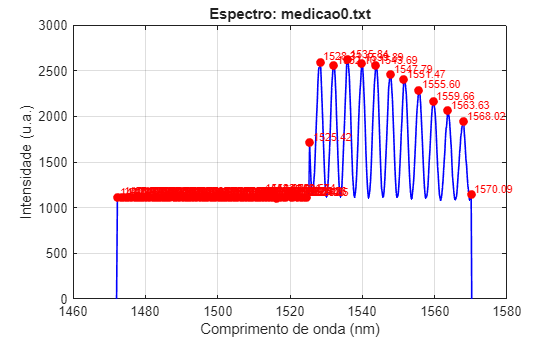

Ficheiro: medicao0.txt  |  picos detectados: 92


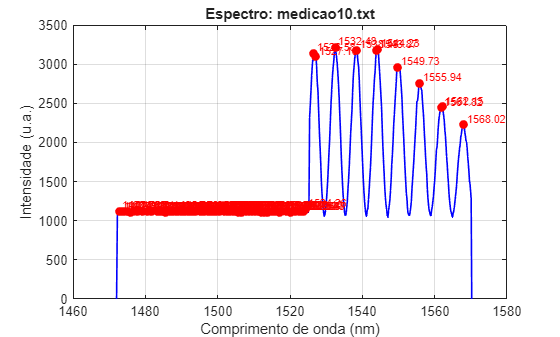

Ficheiro: medicao10.txt  |  picos detectados: 87


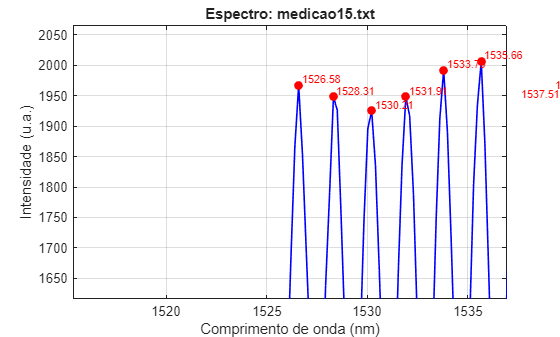

Ficheiro: medicao15.txt  |  picos detectados: 108


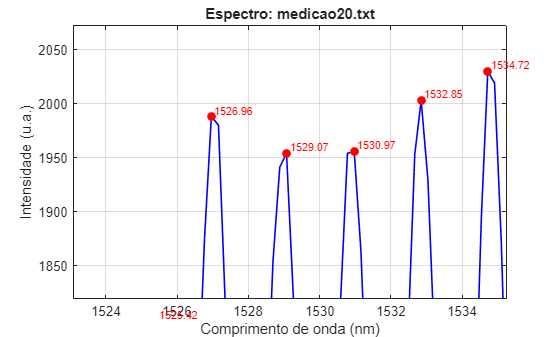

Ficheiro: medicao20.txt  |  picos detectados: 107


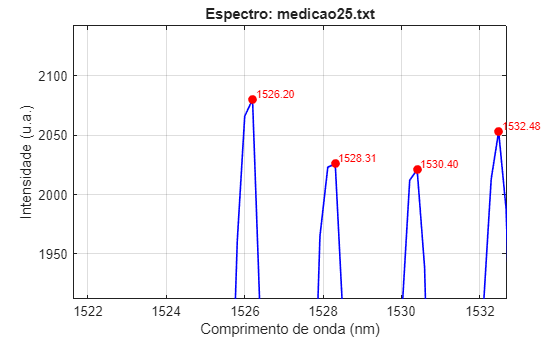

Ficheiro: medicao25.txt  |  picos detectados: 106


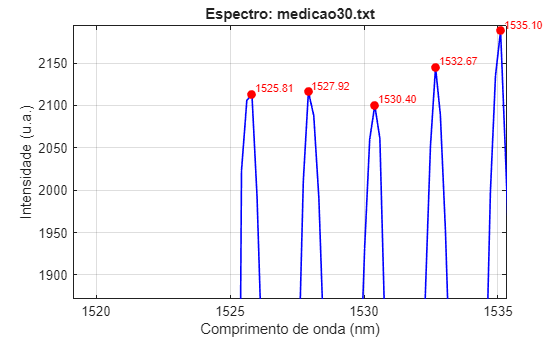

Ficheiro: medicao30.txt  |  picos detectados: 107


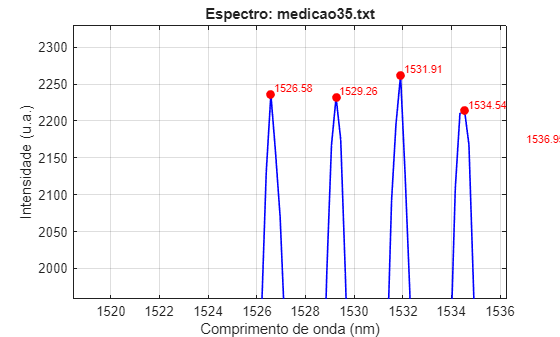

Ficheiro: medicao35.txt  |  picos detectados: 101


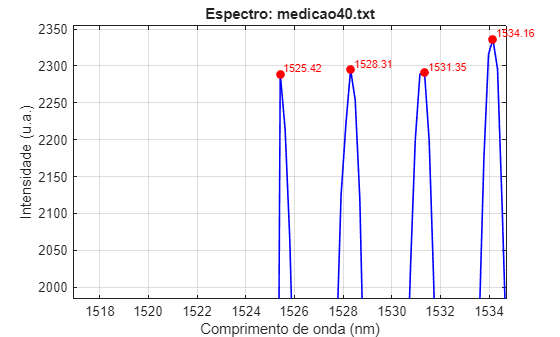

Ficheiro: medicao40.txt  |  picos detectados: 100


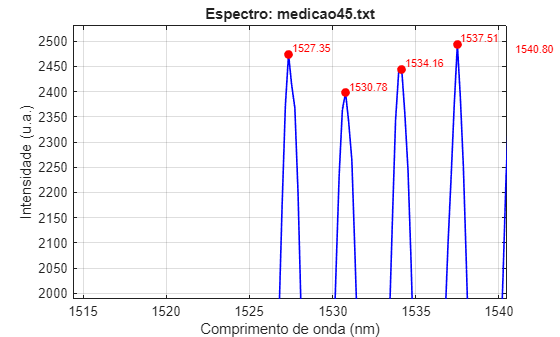

Ficheiro: medicao45.txt  |  picos detectados: 98


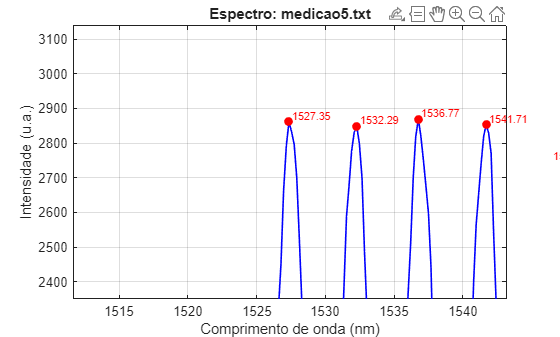

Ficheiro: medicao5.txt  |  picos detectados: 91


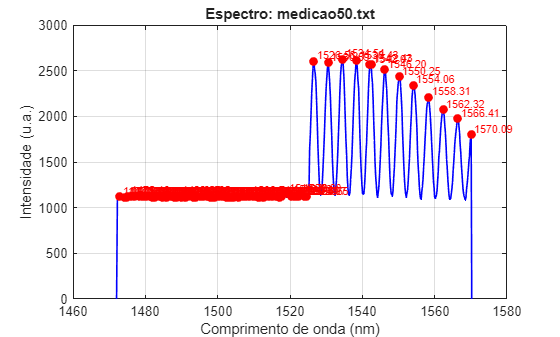

Ficheiro: medicao50.txt  |  picos detectados: 90


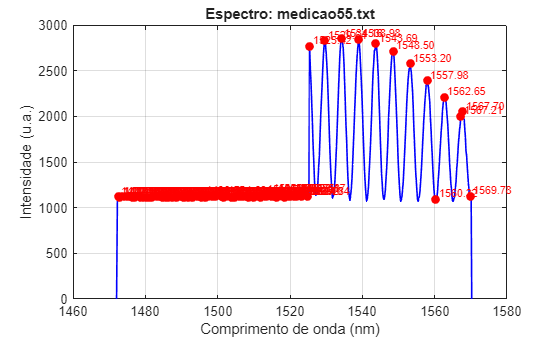

Ficheiro: medicao55.txt  |  picos detectados: 96


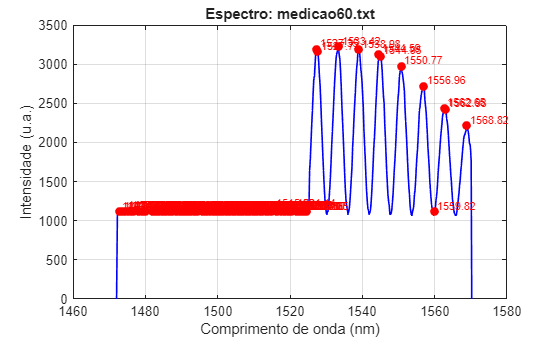

Ficheiro: medicao60.txt  |  picos detectados: 100


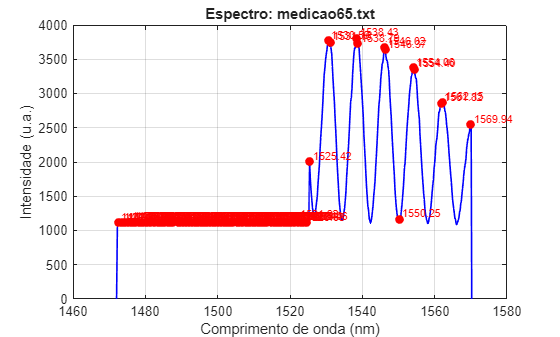

Ficheiro: medicao65.txt  |  picos detectados: 89


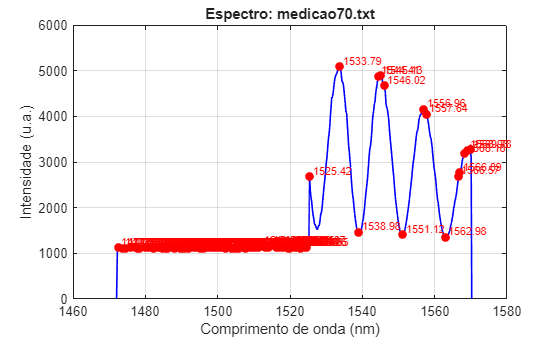

Ficheiro: medicao70.txt  |  picos detectados: 100


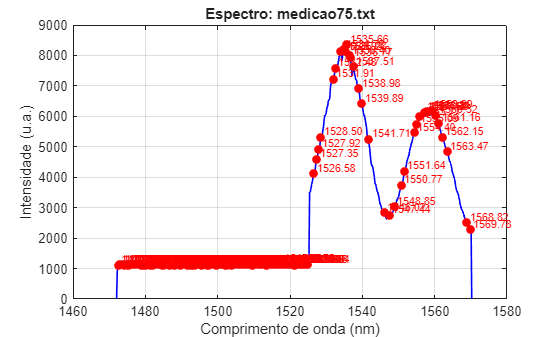

Ficheiro: medicao75.txt  |  picos detectados: 122


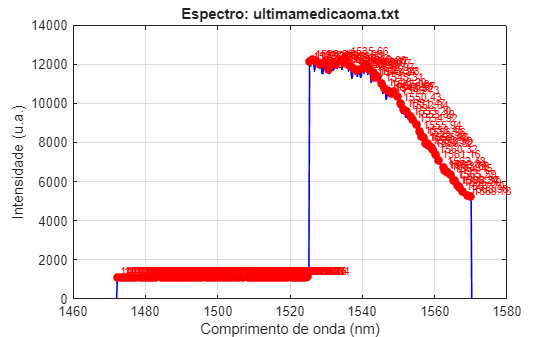

Ficheiro: ultimamedicaoma.txt  |  picos detectados: 146


clc; clear all; close all;

% --- 1. Escolher pasta com ficheiros .txt
pasta = uigetdir(pwd, 'Selecione a pasta com os ficheiros .txt');
if pasta == 0
    disp('Operação cancelada.');
    return;
end

% --- 2. Obter lista de ficheiros .txt
ficheiros = dir(fullfile(pasta, '*.txt'));
if isempty(ficheiros)
    error('Não foram encontrados ficheiros .txt na pasta selecionada.');
end

% --- 3. Coleccionar máximos em cell (cada célula = vector de picos)
colMaximos = cell(1, length(ficheiros));
nomesCol = cell(1, length(ficheiros));

for k = 1:length(ficheiros)
    nomeFicheiro = ficheiros(k).name;
    caminhoFicheiro = fullfile(pasta, nomeFicheiro);

    % Ler ficheiro como texto e substituir vírgula decimal
    try
        txt = fileread(caminhoFicheiro);
        txt = strrep(txt, ',', '.');
    catch
        warning('Erro ao ler %s. Ignorado.', nomeFicheiro);
        continue;
    end

    % Converter em números
    dados = str2num(txt); %#ok<ST2NM>
    if isempty(dados) || size(dados,2) < 2
        warning('Ficheiro %s inválido (precisa de >=2 colunas). Ignorado.', nomeFicheiro);
        continue;
    end

    x = dados(:,1);
    y = dados(:,2);

    % Remover NaNs correspondentes (se existirem)
    valid = ~(isnan(x) | isnan(y) | isinf(x) | isinf(y));
    x = x(valid);
    y = y(valid);

    if isempty(x) || isempty(y)
        warning('Sem dados válidos em %s. Ignorado.', nomeFicheiro);
        continue;
    end

    % Garantir que x e y são vectores coluna
    x = x(:);
    y = y(:);

    % Se x não for estritamente crescente, ordenar por x (mantendo correspondência)
    if any(diff(x) < 0)
        [x, idxSort] = sort(x);
        y = y(idxSort);
    end

    % ---------- Encontrar picos (usar índice, depois mapear para x) ----------
    % Ajusta os parâmetros abaixo se necessário (MinPeakProminence, MinPeakHeight,...)
    [pks, locIdx] = findpeaks(y);           % devolve picos (valores) e índices
    posicoes = x(locIdx);                   % posições em unidades de x

    % Guardar só os valores dos máximos (pks)
    colMaximos{k} = pks(:);                 % vector coluna
    nomesCol{k} = matlab.lang.makeValidName(erase(nomeFicheiro, '.txt'));

    % ---------- Plot individual ----------
    figure;
    plot(x, y, 'b-', 'LineWidth', 1.2);
    hold on;
    plot(posicoes, pks, 'ro', 'MarkerFaceColor', 'r');
    title(sprintf('Espectro: %s', nomeFicheiro), 'Interpreter', 'none');
    xlabel('Comprimento de onda (nm)');
    ylabel('Intensidade (u.a.)');
    grid on;
    for i = 1:length(pks)
        text(posicoes(i), pks(i), sprintf(' %.2f', posicoes(i)), ...
            'VerticalAlignment', 'bottom', 'Color', 'r', 'FontSize', 8);
    end
    hold off;

    fprintf('Ficheiro: %s  |  picos detectados: %d\n', nomeFicheiro, numel(pks));
end


% --- Montar tabela: cada coluna = ficheiro, linhas padded com NaN ---
% Encontrar comprimento máximo
maxLen = max(cellfun(@length, colMaximos));
% Se algum ficheiro foi ignorado, filtrar células vazias
validCells = ~cellfun(@isempty, colMaximos);
colMaximos = colMaximos(validCells);
nomesCol = nomesCol(validCells);

% Preencher matriz com NaN
M = NaN(maxLen, length(colMaximos));
for i = 1:length(colMaximos)
    vec = colMaximos{i};
    M(1:length(vec), i) = vec;
end

% Criar tabela com nomes de colunas
T = array2table(M, 'VariableNames', nomesCol);

% Guardar no Excel
ficheiroExcel = fullfile(pasta, 'Maximos_Espectros.xlsx');
writetable(T, ficheiroExcel);
fprintf('\n✅ Excel criado: %s\n', ficheiroExcel);


✅ Excel criado: C:\Users\joaod\OneDrive\Ambiente de Trabalho\Pastas\3ºano\picos maximo\texctrum\Maximos_Espectros.xlsx
